# **Esercitazione 1 - ECG**

Obiettivo 1: implementare una funzione per identificare i picchi R all'interno di ciascun segnale.

Caricamento del dato nel workspace utilizzando la funzione `load().`

load("data.mat")

Suddivisione del segnale in finestre continue con stessa lunghezza pari a pochi secondi (scelti arbitrareamente) e quindi rimozione del trend lineare tramite l'uso della funzione detrend.

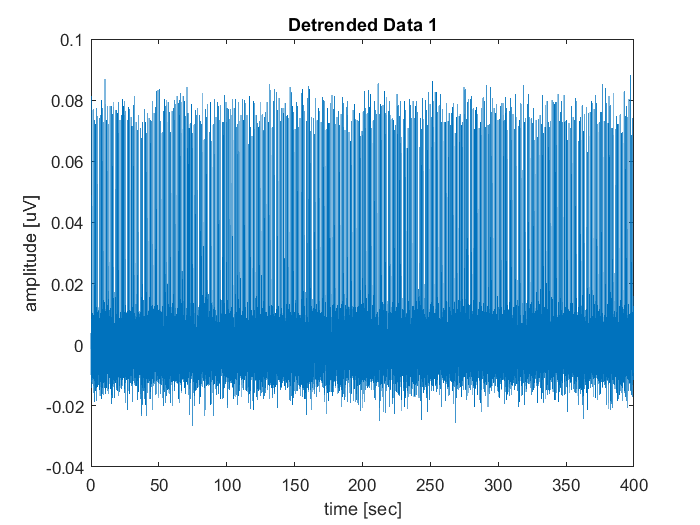

%lunghezza k delle finestre 
k = 1; % [s]

%suddivisione dei segnali
data1 = reshape(data1,fs*k,[]);
data1NoTrend = detrend(data1);

data2 = reshape(data2,fs*k,[]);
data2NoTrend = detrend(data2);

%visualizzazione del risultato ottenuto
data1NoTrend = data1NoTrend(:);

data2NoTrend = data2NoTrend(:);

figure, plot(time,data1NoTrend)
title('Detrended Data 1')
ylabel('amplitude [uV]')
xlabel('time [sec]')

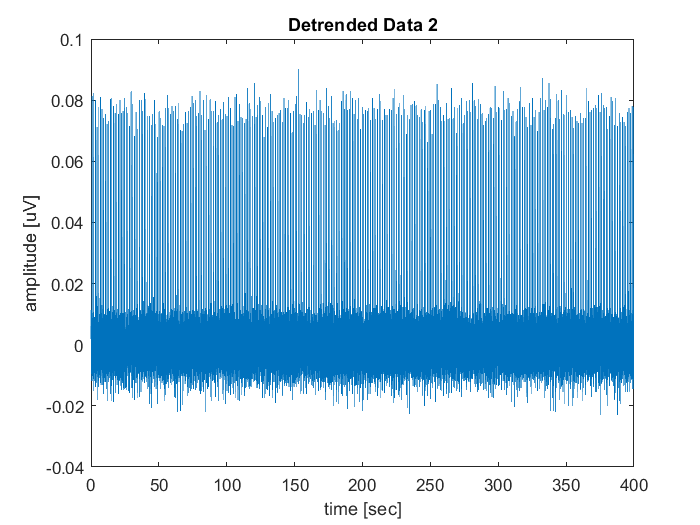

figure, plot(time,data2NoTrend)
title('Detrended Data 2')
ylabel('amplitude [uV]')
xlabel('time [sec]')

Identificazione picchi R tramite una soglia ottima.

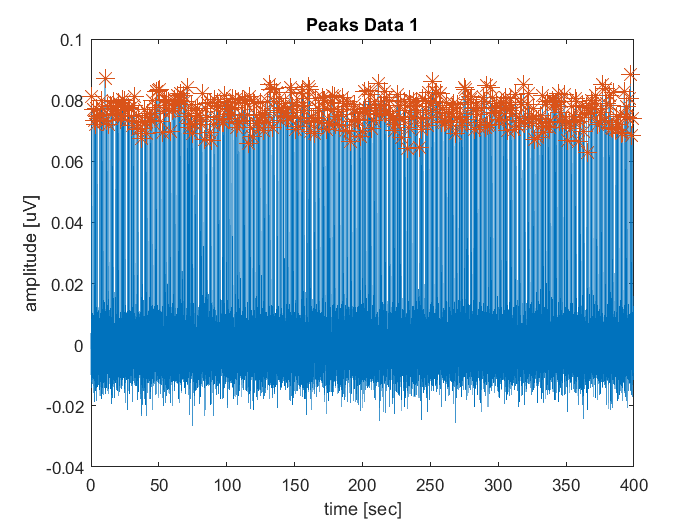

%Utilizzo funzione per il calcolo della soglia ottima
thr=find_thr(data1NoTrend,7.5);
[values1,MaxInd1] = findpeaks(data1NoTrend,fs,'MinPeakHeight',  thr);

figure, plot(time, data1NoTrend)
title('Peaks Data 1')
ylabel('amplitude [uV]')
xlabel('time [sec]')

hold on
plot(MaxInd1,values1,'*','MarkerSize',10)
hold off

%scatter(time(MaxInd),data1NoTrend(MaxInd), [], "red", "filled")]

thr=find_thr(data2NoTrend,7.5)

thr = 0.0483

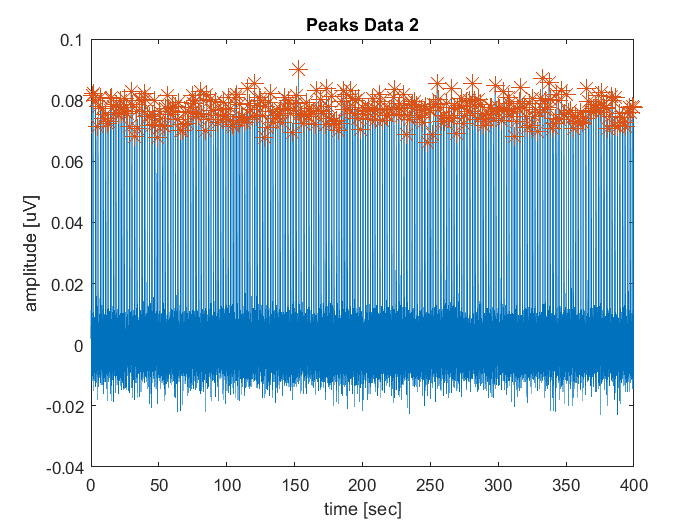

[values2,MaxInd2] = findpeaks(data2NoTrend,fs,'MinPeakHeight',  thr);

figure,plot(time, data2NoTrend)
title('Peaks Data 2')
ylabel('amplitude [uV]')
xlabel('time [sec]')

hold on
plot(MaxInd2,values2,'*','MarkerSize',10)
hold off

Obiettivo 2: implementare una funzione compute_heart_rate per stimare la frequenza del battito cardiaco.

%function heart_rate = compute_heart_rate(input)
dist_RR1=MaxInd1(2:end)-MaxInd1(1:end-1);
dist_RR2=MaxInd2(2:end)-MaxInd2(1:end-1);

Obiettivo 3: implementare una funzione per il calcolo della durata del complezzo QRS e per la visualizzazione del complesso QRS medio.

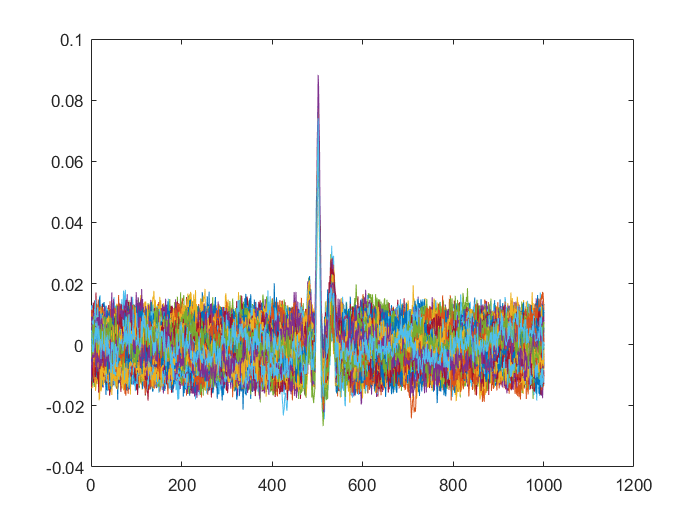


dist_media1=round(mean(dist_RR1));

meta_dist1=dist_media1/2;
 
%matrice che contiene i singoli tracciati [numero campioni x numero battiti]
solo_tracciato1=zeros(dist_media1*fs+1, length(MaxInd1));

figure 

for j=1:length(MaxInd1) 
    solo_tracciato1 (:, j ) = data1NoTrend ( fs*(MaxInd1(j)-meta_dist1) : fs*(MaxInd1(j)+meta_dist1) ) ;   
    plot(solo_tracciato1 (:, j ))
    hold on
end


valmin=zeros([],length(MaxInd1));
xmin=zeros([],length(MaxInd1));

for m=1:length(MaxInd1) 
    [valmin(m), xmin(m)] = findpeaks (- solo_tracciato1 (j, 1:MaxInd1(m))     );
end

Error using findpeaks
Expected Y to be nonempty.

Error in findpeaks>parse_inputs (line 199)
validateattributes(Yin,{'double','single'},{'nonempty','real','vector'},...

Error in findpeaks (line 136)
  = parse_inputs(isInMATLAB,Yin,varargin{:});


solo_tracciato1=solo_tracciato1';
solo_medio1=mean(solo_tracciato1);

plot(solo_medio1, "k", "LineWidth", 1.5);
hold off

dist_media2=round(mean(dist_RR2));

meta_dist2=dist_media2/5;

solo_tracciato2=zeros(length(MaxInd2), fs*meta_dist2*2+1);

figure 

for j=1:length(MaxInd2)
    solo_tracciato2(j,:)=data2NoTrend(fs*(MaxInd2(j)-meta_dist2) : fs*(MaxInd2(j)+meta_dist2));
    
    
    
    plot(solo_tracciato2(j,:))
    hold on
end

solo_medio2=mean(solo_tracciato2);

plot(solo_medio2, "k", "LineWidth", 1.5);
hold off


Obiettivo 4: implementare una funzione per la stima della densità di probabilità delle variabili derivate da ECG per descrivere i ritmi cardiaci.

...

Istogramma delle variabili derivate dall'ECG per entrambi i ritmi cardiaci.